clc
clear
close all

load F:\matlab\bin\App_Desgin\tianjing.mat

%PM25_Concentration	PM10_Concentration	NO2_Concentration	CO_Concentration	O3_Concentration	SO2_Concentration	
data = tianjing;
PM25 = data(:,1);
PM25 = fillmissing(PM25,"linear");
PM25 = PM25';
PM10 = data(:,2);
PM10 = fillmissing(PM10,"linear");
PM10 = PM10';
NO2 = data(:,3);
NO2 = fillmissing(NO2,"linear");
NO2 = NO2';
CO = data(:,4);
CO = fillmissing(CO,"linear");
CO = CO';
O3 = data(:,5);
O3 = fillmissing(O3,"linear");
O3 = O3';
SO2 = data(:,6);
SO2 = fillmissing(SO2,"linear");
SO2 = SO2';


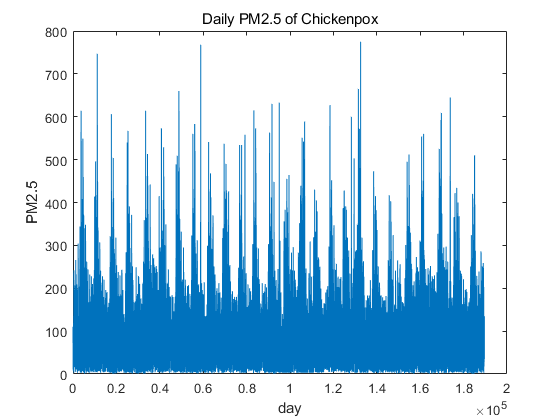

figure
plot(PM25)
xlabel("day")
ylabel("PM2.5")
title("Daily PM2.5 of Chickenpox")


numTimeStepsTrain = floor(0.9*numel(PM25));

dataTrain = PM25(1:numTimeStepsTrain+1);
dataTest = PM25(numTimeStepsTrain+1:end);

mu = mean(dataTrain);
sig = std(dataTrain);

dataTrainStandardized = (dataTrain - mu) / sig;

XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);

numFeatures = 1;
numResponses = 1;
numHiddenUnits = 250;

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];

options = trainingOptions('adam', ...
    'MaxEpochs',50, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');

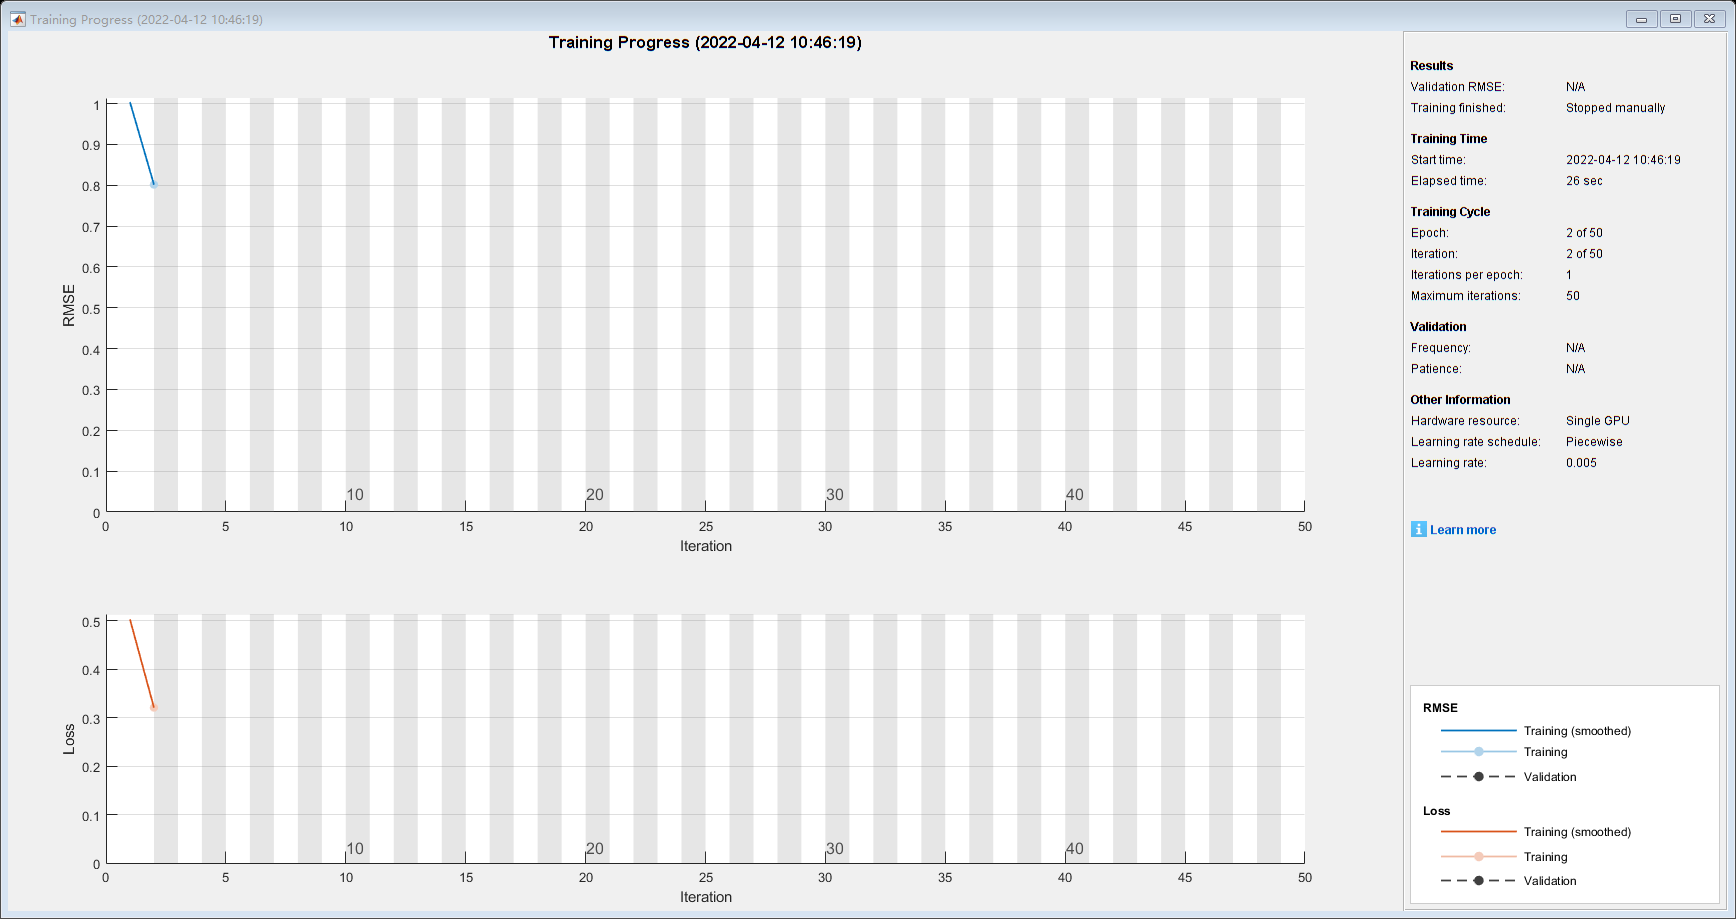

net = trainNetwork(XTrain,YTrain,layers,options);

save('PM25LSTM.mat','net');

dataTestStandardized = (dataTest - mu) / sig;
XTest = dataTestStandardized(1:end-1);

net = predictAndUpdateState(net,XTrain);
[net,YPred] = predictAndUpdateState(net,YTrain(end));

numTimeStepsTest = numel(XTest);
for i = 2:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,YPred(:,i-1),'ExecutionEnvironment','cpu');
end

YPred = sig*YPred + mu;


YTest = dataTest(2:end);
rmse = sqrt(mean((YPred-YTest).^2))


figure
plot(dataTrain(1:end-1))
hold on
idx = numTimeStepsTrain:(numTimeStepsTrain+numTimeStepsTest);
plot(idx,[PM25(numTimeStepsTrain) YPred],'.-')
hold off
xlabel("Month")
ylabel("Cases")
title("Forecast")
legend(["Observed" "Forecast"])


figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Forecast"])
ylabel("Cases")
title("Forecast")

subplot(2,1,2)
stem(YPred - YTest)
xlabel("Month")
ylabel("Error")
title("RMSE = " + rmse)

net = resetState(net);
net = predictAndUpdateState(net,XTrain);

YPred = [];
numTimeStepsTest = numel(XTest);
for i = 1:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,XTest(:,i),'ExecutionEnvironment','cpu');
end

YPred = sig*YPred + mu;

rmse = sqrt(mean((YPred-YTest).^2))


figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Predicted"])
ylabel("Cases")
title("Forecast with Updates")

subplot(2,1,2)
stem(YPred - YTest)
xlabel("Month")
ylabel("Error")
title("RMSE = " + rmse)



PM10

figure
plot(PM10)
xlabel("day")
ylabel("PM10")
title("Daily PM10 of Chickenpox")


numTimeStepsTrain = floor(0.9*numel(PM10));

dataTrain = PM10(1:numTimeStepsTrain+1);
dataTest = PM10(numTimeStepsTrain+1:end);

mu = mean(dataTrain);
sig = std(dataTrain);

dataTrainStandardized = (dataTrain - mu) / sig;

XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);

numFeatures = 1;
numResponses = 1;
numHiddenUnits = 250;

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];

options = trainingOptions('adam', ...
    'MaxEpochs',50, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');

net = trainNetwork(XTrain,YTrain,layers,options);
save('PM10LSTM.mat','net');

dataTestStandardized = (dataTest - mu) / sig;
XTest = dataTestStandardized(1:end-1);

net = predictAndUpdateState(net,XTrain);
[net,YPred] = predictAndUpdateState(net,YTrain(end));

numTimeStepsTest = numel(XTest);
for i = 2:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,YPred(:,i-1),'ExecutionEnvironment','cpu');
end

YPred = sig*YPred + mu;


YTest = dataTest(2:end);
rmse = sqrt(mean((YPred-YTest).^2))


figure
plot(dataTrain(1:end-1))
hold on
idx = numTimeStepsTrain:(numTimeStepsTrain+numTimeStepsTest);
plot(idx,[PM25(numTimeStepsTrain) YPred],'.-')
hold off
xlabel("Month")
ylabel("Cases")
title("Forecast")
legend(["Observed" "Forecast"])


figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Forecast"])
ylabel("Cases")
title("Forecast")

subplot(2,1,2)
stem(YPred - YTest)
xlabel("Month")
ylabel("Error")
title("RMSE = " + rmse)

net = resetState(net);
net = predictAndUpdateState(net,XTrain);

YPred = [];
numTimeStepsTest = numel(XTest);
for i = 1:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,XTest(:,i),'ExecutionEnvironment','cpu');
end

YPred = sig*YPred + mu;

rmse = sqrt(mean((YPred-YTest).^2))


figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Predicted"])
ylabel("Cases")
title("Forecast with Updates")

subplot(2,1,2)
stem(YPred - YTest)
xlabel("Month")
ylabel("Error")
title("RMSE = " + rmse)

NO2


figure
plot(NO2)
xlabel("day")
ylabel("NO2")
title("Daily NO2 of Chickenpox")


numTimeStepsTrain = floor(0.9*numel(NO2));

dataTrain = NO2(1:numTimeStepsTrain+1);
dataTest = NO2(numTimeStepsTrain+1:end);

mu = mean(dataTrain);
sig = std(dataTrain);

dataTrainStandardized = (dataTrain - mu) / sig;

XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);

numFeatures = 1;
numResponses = 1;
numHiddenUnits = 250;

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];

options = trainingOptions('adam', ...
    'MaxEpochs',50, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');

net = trainNetwork(XTrain,YTrain,layers,options);
save('NO2LSTM.mat','net');

dataTestStandardized = (dataTest - mu) / sig;
XTest = dataTestStandardized(1:end-1);

net = predictAndUpdateState(net,XTrain);
[net,YPred] = predictAndUpdateState(net,YTrain(end));

numTimeStepsTest = numel(XTest);
for i = 2:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,YPred(:,i-1),'ExecutionEnvironment','cpu');
end

YPred = sig*YPred + mu;


YTest = dataTest(2:end);
rmse = sqrt(mean((YPred-YTest).^2))


figure
plot(dataTrain(1:end-1))
hold on
idx = numTimeStepsTrain:(numTimeStepsTrain+numTimeStepsTest);
plot(idx,[PM25(numTimeStepsTrain) YPred],'.-')
hold off
xlabel("Month")
ylabel("Cases")
title("Forecast")
legend(["Observed" "Forecast"])


figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Forecast"])
ylabel("Cases")
title("Forecast")

subplot(2,1,2)
stem(YPred - YTest)
xlabel("Month")
ylabel("Error")
title("RMSE = " + rmse)

net = resetState(net);
net = predictAndUpdateState(net,XTrain);

YPred = [];
numTimeStepsTest = numel(XTest);
for i = 1:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,XTest(:,i),'ExecutionEnvironment','cpu');
end

YPred = sig*YPred + mu;

rmse = sqrt(mean((YPred-YTest).^2))


figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Predicted"])
ylabel("Cases")
title("Forecast with Updates")

subplot(2,1,2)
stem(YPred - YTest)
xlabel("Month")
ylabel("Error")
title("RMSE = " + rmse)

CO

figure
plot(CO)
xlabel("day")
ylabel("CO")
title("Daily CO of Chickenpox")


numTimeStepsTrain = floor(0.9*numel(CO));

dataTrain = CO(1:numTimeStepsTrain+1);
dataTest = CO(numTimeStepsTrain+1:end);

mu = mean(dataTrain);
sig = std(dataTrain);

dataTrainStandardized = (dataTrain - mu) / sig;

XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);

numFeatures = 1;
numResponses = 1;
numHiddenUnits = 250;

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];

options = trainingOptions('adam', ...
    'MaxEpochs',50, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');

net = trainNetwork(XTrain,YTrain,layers,options);
save('COLSTM.mat','net');

dataTestStandardized = (dataTest - mu) / sig;
XTest = dataTestStandardized(1:end-1);

net = predictAndUpdateState(net,XTrain);
[net,YPred] = predictAndUpdateState(net,YTrain(end));

numTimeStepsTest = numel(XTest);
for i = 2:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,YPred(:,i-1),'ExecutionEnvironment','cpu');
end

YPred = sig*YPred + mu;


YTest = dataTest(2:end);
rmse = sqrt(mean((YPred-YTest).^2))


figure
plot(dataTrain(1:end-1))
hold on
idx = numTimeStepsTrain:(numTimeStepsTrain+numTimeStepsTest);
plot(idx,[PM25(numTimeStepsTrain) YPred],'.-')
hold off
xlabel("Month")
ylabel("Cases")
title("Forecast")
legend(["Observed" "Forecast"])


figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Forecast"])
ylabel("Cases")
title("Forecast")

subplot(2,1,2)
stem(YPred - YTest)
xlabel("Month")
ylabel("Error")
title("RMSE = " + rmse)

net = resetState(net);
net = predictAndUpdateState(net,XTrain);

YPred = [];
numTimeStepsTest = numel(XTest);
for i = 1:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,XTest(:,i),'ExecutionEnvironment','cpu');
end

YPred = sig*YPred + mu;

rmse = sqrt(mean((YPred-YTest).^2))


figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Predicted"])
ylabel("Cases")
title("Forecast with Updates")

subplot(2,1,2)
stem(YPred - YTest)
xlabel("Month")
ylabel("Error")
title("RMSE = " + rmse)

O3

figure
plot(O3)
xlabel("day")
ylabel("O3")
title("Daily O3 of Chickenpox")


numTimeStepsTrain = floor(0.9*numel(O3));

dataTrain = O3(1:numTimeStepsTrain+1);
dataTest = O3(numTimeStepsTrain+1:end);

mu = mean(dataTrain);
sig = std(dataTrain);

dataTrainStandardized = (dataTrain - mu) / sig;

XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);

numFeatures = 1;
numResponses = 1;
numHiddenUnits = 250;

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];

options = trainingOptions('adam', ...
    'MaxEpochs',50, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');

net = trainNetwork(XTrain,YTrain,layers,options);
save('O3LSTM.mat','net');

dataTestStandardized = (dataTest - mu) / sig;
XTest = dataTestStandardized(1:end-1);

net = predictAndUpdateState(net,XTrain);
[net,YPred] = predictAndUpdateState(net,YTrain(end));

numTimeStepsTest = numel(XTest);
for i = 2:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,YPred(:,i-1),'ExecutionEnvironment','cpu');
end

YPred = sig*YPred + mu;


YTest = dataTest(2:end);
rmse = sqrt(mean((YPred-YTest).^2))


figure
plot(dataTrain(1:end-1))
hold on
idx = numTimeStepsTrain:(numTimeStepsTrain+numTimeStepsTest);
plot(idx,[PM25(numTimeStepsTrain) YPred],'.-')
hold off
xlabel("Month")
ylabel("Cases")
title("Forecast")
legend(["Observed" "Forecast"])


figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Forecast"])
ylabel("Cases")
title("Forecast")

subplot(2,1,2)
stem(YPred - YTest)
xlabel("Month")
ylabel("Error")
title("RMSE = " + rmse)

net = resetState(net);
net = predictAndUpdateState(net,XTrain);

YPred = [];
numTimeStepsTest = numel(XTest);
for i = 1:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,XTest(:,i),'ExecutionEnvironment','cpu');
end

YPred = sig*YPred + mu;

rmse = sqrt(mean((YPred-YTest).^2))


figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Predicted"])
ylabel("Cases")
title("Forecast with Updates")

subplot(2,1,2)
stem(YPred - YTest)
xlabel("Month")
ylabel("Error")
title("RMSE = " + rmse)

SO2

figure
plot(SO2)
xlabel("day")
ylabel("SO2")
title("Daily SO2 of Chickenpox")


numTimeStepsTrain = floor(0.9*numel(SO2));

dataTrain = SO2(1:numTimeStepsTrain+1);
dataTest = SO2(numTimeStepsTrain+1:end);

mu = mean(dataTrain);
sig = std(dataTrain);

dataTrainStandardized = (dataTrain - mu) / sig;

XTrain = dataTrainStandardized(1:end-1);
YTrain = dataTrainStandardized(2:end);

numFeatures = 1;
numResponses = 1;
numHiddenUnits = 250;

layers = [ ...
    sequenceInputLayer(numFeatures)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(numResponses)
    regressionLayer];

options = trainingOptions('adam', ...
    'MaxEpochs',50, ...
    'GradientThreshold',1, ...
    'InitialLearnRate',0.005, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',125, ...
    'LearnRateDropFactor',0.2, ...
    'Verbose',0, ...
    'Plots','training-progress');

net = trainNetwork(XTrain,YTrain,layers,options);
save('SO2LSTM.mat','net');

dataTestStandardized = (dataTest - mu) / sig;
XTest = dataTestStandardized(1:end-1);

net = predictAndUpdateState(net,XTrain);
[net,YPred] = predictAndUpdateState(net,YTrain(end));

numTimeStepsTest = numel(XTest);
for i = 2:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,YPred(:,i-1),'ExecutionEnvironment','cpu');
end

YPred = sig*YPred + mu;


YTest = dataTest(2:end);
rmse = sqrt(mean((YPred-YTest).^2))


figure
plot(dataTrain(1:end-1))
hold on
idx = numTimeStepsTrain:(numTimeStepsTrain+numTimeStepsTest);
plot(idx,[PM25(numTimeStepsTrain) YPred],'.-')
hold off
xlabel("Month")
ylabel("Cases")
title("Forecast")
legend(["Observed" "Forecast"])


figure
subplot(2,1,1)
plot(YTest)
hold on
plot(YPred,'.-')
hold off
legend(["Observed" "Forecast"])
ylabel("Cases")
title("Forecast")

subplot(2,1,2)
stem(YPred - YTest)
xlabel("Month")
ylabel("Error")
title("RMSE = " + rmse)

net = resetState(net);
net = predictAndUpdateState(net,XTrain);

YPred = [];
numTimeStepsTest = numel(XTest);
for i = 1:numTimeStepsTest
    [net,YPred(:,i)] = predictAndUpdateState(net,XTest(:,i),'ExecutionEnvironment','cpu');
end

YPred = sig*YPred + mu;

rmse = sqrt(mean((YPred-YTest).^2))